bactch multiField channel register test1

align XY using fft   cross-correlation

% 目前来看 效果不好，大视野明场图像并不能很好对齐 以F:\2020-06-11-CyOFP tracking test ys\field0001\BF1 图像进行测试

% Shuai Yang 2020.09.21

核心函数[output, Greg] = dftregistration(buf1ft,buf2ft,usfac)

%https://www.mathworks.com/matlabcentral/fileexchange/18401-efficient-subpixel-image-registration-by-cross-correlation

% 修改了parfor运行时的广播变量问题 Shuai Yang 2021.06.29

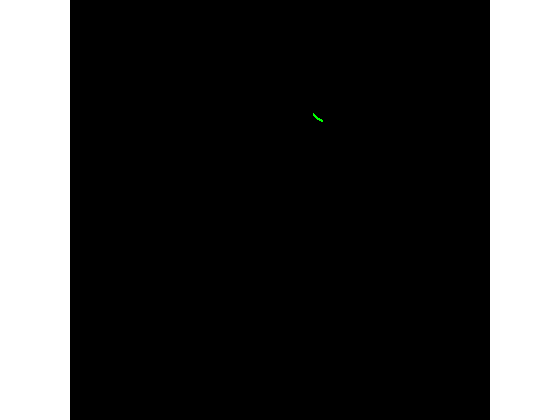

I0 = imageCyOFP00002;
I1 = imageCyOFP00003;

priorIm = imageCyOFP00002;
afterIm = imageCyOFP00003;

priorIm = fluoImCellSeg_ys(priorIm);

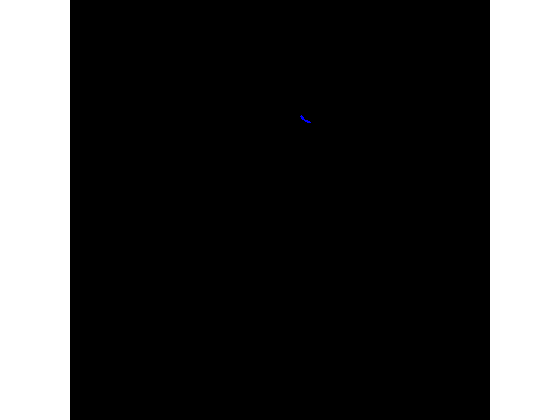

afterIm = fluoImCellSeg_ys(afterIm);

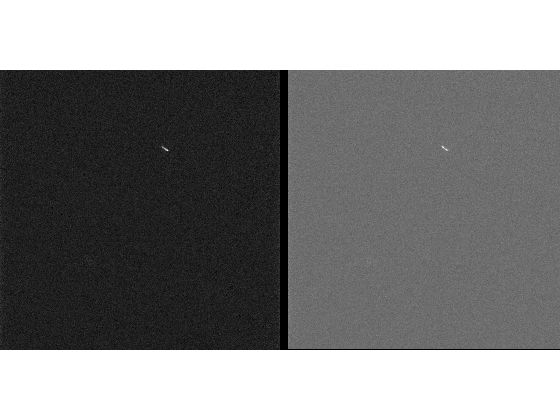


% priorIm = im2double(priorIm);
% afterIm = im2double(afterIm);

fft_priorIm = fft2(priorIm);
fft_afterIm = fft2(afterIm);



usfac = 1;
[output, ~] = dftregistration(fft_priorIm,fft_afterIm,usfac);

XYtransArray = output(:,[4,3]);

imOut = imtranslate( I1, XYtransArray,'FillValues', 0);

imshowpair(I0,imOut,'montage');

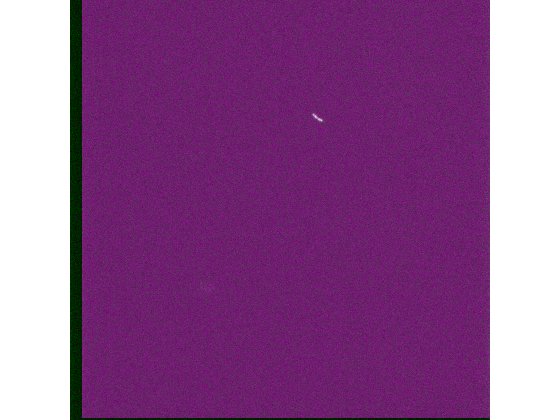

imshowpair(I0,imOut,'falsecolor');

% tic;
% 
% allChannels = {'BF1','PVD','Venus','sfGFP','mScarletI','CyOFP','TDsmURFP'};
% baseChannel = 'CyOFP';
% dirFile = 'E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\align test2';
% % dirFile = 'F:\2020-06-11-CyOFP tracking test ys';
% fieldList = dir([dirFile,filesep,'field*']);
% usfac = 1;
% for iField = 1%:numel(fieldList)
%     dirField = [dirFile,filesep,fieldList(iField).name];
%     channelList = dir(dirField);
%     disp (fieldList(iField).name);
%     
%     
%     channelTF = false(size(allChannels));
%     for iChannel = 1:length(channelList)
%         
%         if(isequal(channelList(iChannel).name,'.')||...
%                 isequal(channelList(iChannel).name,'..')||...
%                 ~channelList(iChannel).isdir)
%             continue;
%         end
%         
%         [Lia,Locb] = ismember(channelList(iChannel).name,allChannels);
%         if Lia
%             channelTF(Locb) = true;
%         end
%         
%     end
%     existChannels = allChannels(channelTF);
%     % 以phase image 进行xy shift 矫正
%     if ismember(baseChannel,existChannels)
%         imList = dir([dirField,filesep,baseChannel,filesep,'*.tif']);
%         outPut_Array = zeros(numel(imList)-1,4);
%         
%         priorImList = imList(1:end-1);
%         afterImList = imList(2:end);
%         
%         parfor iImage = 1:numel(priorImList)
%             priorIm = imread([dirField,filesep,baseChannel,filesep,priorImList(iImage).name]);
%             afterIm = imread([dirField,filesep,baseChannel,filesep,afterImList(iImage).name]);
%             
%             priorIm = im2double(priorIm);
%             afterIm = im2double(afterIm);
%             %rescales the output from integer data types to the range [0, 1].
%             
%             %             priorIm = rescale(double(priorIm));% rescale [0 1]
%             %             afterIm = rescale(double(afterIm));
%             %             priorIm = cast(priorIm*255,'uint8');% convert to 8bit
%             %             afterIm = cast(afterIm*255,'uint8');
%             % fourier transform images
%             fft_priorIm = fft2(priorIm);
%             fft_afterIm = fft2(afterIm);
%             
%             [output, ~] = dftregistration(fft_priorIm,fft_afterIm,usfac);
%             outPut_Array(iImage,:) = output;
%         end
%     end
%     xyshiftPixels = outPut_Array(:,end-1:end);%第3和4列是xy方向的平移pixel大小
%     cumXYshift = cumsum(xyshiftPixels,1);%Cumulative 累积的xy偏移量
%     
%     
%     cumShift_Array(:,1:2) = outPut_Array(:,1:2);%累计的Pixel shifts between images
%     cumShift_Array(:,3:4) = cumXYshift;
%     
%     %     cumShift_Array = outPut_Array;
%     %     for i = 2 :size(accuShift_Array,1)
%     %         cumShift_Array(i,end-1:end) = ...
%     %             cumShift_Array(i,end-1:end)+cumShift_Array(i-1,end-1:end);
%     %     end
%     %     用cumsum函数代替
%     
%     dirNew = [dirField,filesep,baseChannel,'_New1'];
%     if ~isfolder(dirNew)
%         mkdir(dirNew)
%     end
%     XYtransArray = cumXYshift(:,[2,1]);
%     parfor iImage = 1:numel(afterImList)
%         imIn = imread([dirField,filesep,baseChannel,filesep,afterImList(iImage).name]);
%         imOut = imtranslate( imIn, XYtransArray(iImage,:),'FillValues', min(imIn(:)));
%         imwrite(imOut,[dirNew,filesep,afterImList(iImage).name]);
%     end
%     
% end
% toc;
